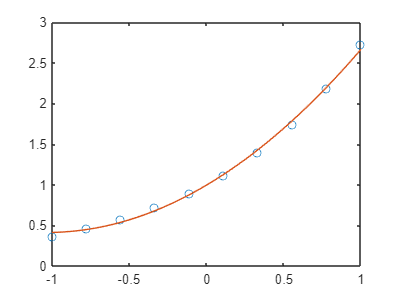

%% Creare un'interpolazione polinomiale di una funzione data

% Creo i punti da interpolare
x = linspace(-1, 1, 10);
y = exp(x);

% Calcolo i coefficenti tramite polyfit
coeff = polyfit(x, y, 2);

% Creo i nuovi punti della funzione che interpoleranno l'originale
interp = linspace(-1, 1, 100);
y_interp = polyval(coeff, interp);

% Plot del risultato
plot(x, y, 'o' ,interp, y_interp, '-');